# Control and Instrumentation Lab Assignment 2

**SWARNENDU PAUL 19EE3FP18**

**Question 1**

The script for the function is given in the zip file as euler_sol.m

**Question 2.a.**

Function $\frac{dy(t)}{dt} = 2$ is saved in f1.m

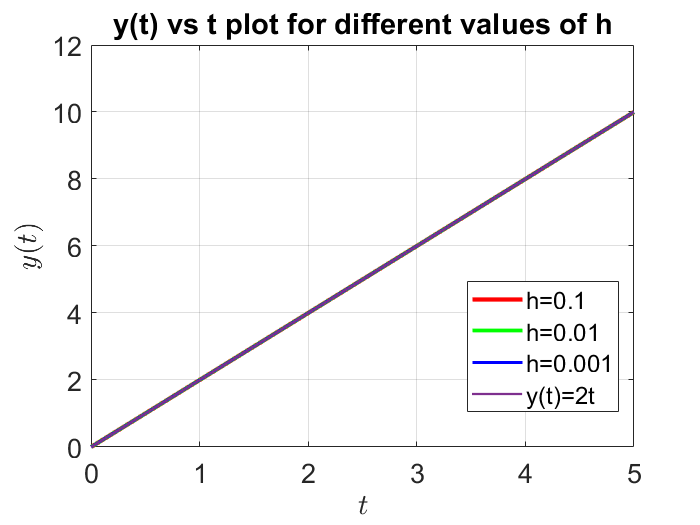

Tfunc_1=zeros(1,3);
Tfunc_2=zeros(1,3);
error_1=zeros(1,3);
error_2=zeros(1,3);
tic
[t1, y1]=euler_sol(@f1,0,5,0,0.1);
Tfunc_1(1)=toc;
tic
[t2, y2]=euler_sol(@f1,0,5,0,0.01);
Tfunc_1(2)=toc;
tic
[t3, y3]=euler_sol(@f1,0,5,0,0.001);
Tfunc_1(3)=toc;
h1=plot(t1,y1,"r-",t2,y2,"g-",t3,y3,"b-");
hold on 
fplot(@(t) 2.*t,[0 5],'LineWidth',1.4);
hold off
set(h1,{'LineWidth'},{2.6;2.2;1.8});
xlabel('$t$','Interpreter',"latex");
ylabel('$y(t)$','Interpreter',"latex");
grid on
set(gca,'Fontsize',16);
legend('h=0.1','h=0.01','h=0.001','y(t)=2t',"Location","best");
title('y(t) vs t plot for different values of h');

From the plot we notice that irrespective of the values of h, the plot generated is same as the resultant solution of the ODE. This is because the function $y(t) = 2t$ is an one degree polynomial.

**Question 2.b.**

Function $\frac{dy(t)}{dt} = 3t^2$ is saved in f2.m

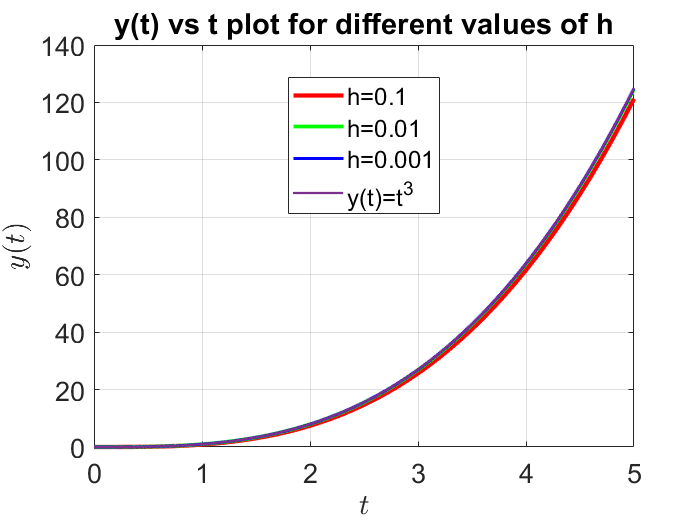

tic
[t4, y4]=euler_sol(@f2,0,5,0,0.1);
Tfunc_2(1)=toc;
tic
[t5, y5]=euler_sol(@f2,0,5,0,0.01);
Tfunc_2(2)=toc;
tic
[t6, y6]=euler_sol(@f2,0,5,0,0.001);
Tfunc_2(3)=toc;
h2=plot(t4,y4,"r-",t5,y5,"g-",t6,y6,"b-");
hold on 
fplot(@(t) t.^3,[0 5],'LineWidth',1.4);
hold off
set(h2,{'LineWidth'},{2.6;2.2;1.8});
xlabel('$t$','Interpreter',"latex");
ylabel('$y(t)$','Interpreter',"latex");
grid on
set(gca,'Fontsize',16);
legend('h=0.1','h=0.01','h=0.001','y(t)=t^3',"Location","best");
title('y(t) vs t plot for different values of h');

From the plot, we can observe as we decrease the value of h, the plot generated approaches closer to the ideal function $y = t^3$.

Now let's find the accuracy using norm() function to actually visualize the difference.

For the first function(when h=0.1)

error_1(1)=norm(y1-2.*t1);
error_1(1)

ans = 1.5424e-14

Which is in the order of $10^{-14}$ so almost 0.

For the first function(when h=0.01)

error_1(2)=norm(y2-2.*t2);
error_1(2)

ans = 1.2345e-12

Same as before.

For the first function(when h=0.001)

error_1(3)=norm(y3-2.*t3);
error_1(3)

ans = 2.4000e-11

Which is again ~0.

Now, for the second function(when h=0.1)

error_2(1)=norm(y4-t4.^3);
error_2(1)

ans = 12.0550

Now, we can observe a significant difference.

Again for h=0.01

error_2(2)=norm(y5-t5.^3);
error_2(2)

ans = 3.7562

As we decrease h the generated solution of ODE gets closer to the actual solution i.e. accuracy increases.

For h=0.001

error_2(3)=norm(y6-t6.^3);
error_2(3)

ans = 1.1861

The data becomes even more accurate when h=0.001 

We have also stored the time required to calculate each trajectory ${t_n},{y_n}$ pair of vectors in Tfunc_1,Tfunc_2. To calculate the trajectories using smaller value of h will require more number of calculations so it will definitely take more time.

Lets print the T arrays where we stored the time required to calculate the trajectories in order h = 0.1,0.01,0.001 

Tfunc_1

Tfunc_1 =     0.0180    0.0075    0.0125


Tfunc_2

Tfunc_2 =     0.0049    0.0051    0.0089


From the observed time data, It is evident that time taken increases linearly with number of t values we calculate y for. So as we decrease h, time taken to calculate trajectory increases.

**Question 3**

The script for the function is given in the zip file as RK4_sol.m

**Question 4**

Now the ODE $\frac{dy(t)}{dt} = 3t^2$ is solved using the RK4 method and same parameters are created to compute accuracy and time taken to compute the trajectories.

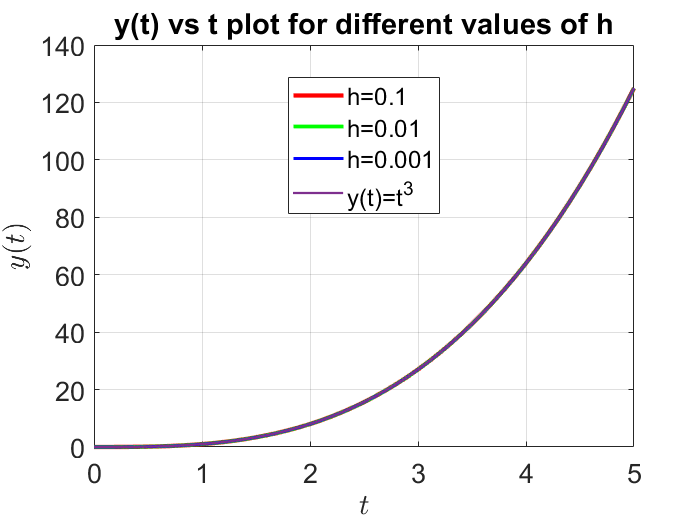

Tfunc_2RK4=zeros(1,3);
error_2RK4=zeros(1,3);
tic
[t7, y7]=RK4_sol(@f2,0,5,0,0.1);
Tfunc_2RK4(1)=toc;
tic
[t8, y8]=RK4_sol(@f2,0,5,0,0.01);
Tfunc_2RK4(2)=toc;
tic
[t9, y9]=RK4_sol(@f2,0,5,0,0.001);
Tfunc_2RK4(3)=toc;
h3=plot(t7,y7,"r-",t8,y8,"g-",t9,y9,"b-");
hold on 
fplot(@(t) t.^3,[0 5],'LineWidth',1.4);
hold off
set(h3,{'LineWidth'},{2.6;2.2;1.8});
xlabel('$t$','Interpreter',"latex");
ylabel('$y(t)$','Interpreter',"latex");
grid on
set(gca,'Fontsize',16);
legend('h=0.1','h=0.01','h=0.001','y(t)=t^3',"Location","best");
title('y(t) vs t plot for different values of h');

error_2RK4(1)=norm(y7-t7.^3);
error_2RK4(2)=norm(y8-t8.^3);
error_2RK4(3)=norm(y9-t9.^3);
error_2RK4

error_2RK4 = 	1.0e+-11 *

    0.0058    0.0312    0.3423


As we can observe from the data, accuracy of calculation in RK4 method is much better than euler method as the error in this case is of the order $10^{-11}$.

Now a table is created to compare the completion time and accuracy of euler method and RK4 method for the ODE


$$\frac{dy(t)}{dt} = 3t^2 , y(0)=0$$
 

varTypes=["double" , "double" , "double","double","double"];
varnames=["Step size h","Euler Computation time(s)","RK4 Computation time(s)","Euler accuracy","RK4 accuracy(x10^-11)"];
dim_T=[3 5];
T=table('size',dim_T,'VariableTypes',varTypes,'VariableNames',varnames);
T(:,1)={0.1;0.01;0.001};
T(:,2)=num2cell(transpose(Tfunc_2));
T(:,3)=num2cell(transpose(Tfunc_2RK4));
T(:,4)=num2cell(transpose(error_2));
T(:,5)=num2cell(transpose(error_2RK4.*(1e11)));
T

T = 3×5 table
    Step size h    Euler Computation time(s)    RK4 Computation time(s)    Euler accuracy    RK4 accuracy(x10^-11)
    ___________    _________________________    _______________________    ______________    _____________________

         0.1               0.0048856                   0.0074417               12.055              0.0057502      
        0.01               0.0050572                   0.0059013               3.7562                0.03116      
       0.001               0.0089373                    0.019368               1.1861                0.34227      


The table T shows comparison between RK4 and euler method of solving ODE. RK4 method is more accurate but takes more time to calculate due to extra calculations.

Overall, RK4 is better solution method for ODE.